% ASSIGNMENT 3
% Akash Rout (21103080)

% Question 1

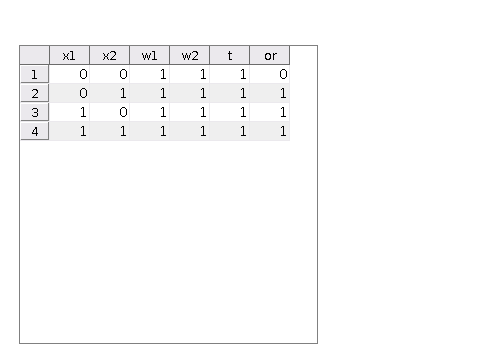

% Part A
% OR Gate

x1 = [0, 0, 1, 1];
x2 = [0, 1, 0, 1];
w1 = [1, 1, 1, 1];
w2 = [1, 1, 1, 1];
t = 1;

or = {'x1' 'x2' 'w1' 'w2' 't' 'or'};
data=[];
for i = 1:length(x1)
    if ( x1(i)*w1(i) + x2(i)*w2(i)) >= t
        datas = [x1(i), x2(i), w1(i), w2(i), t, 1];
    else
        datas = [x1(i), x2(i), w1(i), w2(i), t, 0];
    end
    data = [data; datas];
end

f=figure;
t=uitable(f, 'data', data, 'columnname', or, 'ColumnWidth', {40});

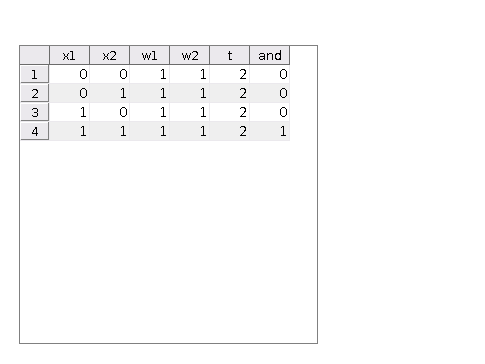

% Part B
% AND Gate

x1 = [0, 0, 1, 1];
x2 = [0, 1, 0, 1];
w1 = [1, 1, 1, 1];
w2 = [1, 1, 1, 1];
t = 2;

and = {'x1' 'x2' 'w1' 'w2' 't' 'and'};
data=[];
for i = 1:length(x1)
    if ( x1(i)*w1(i) + x2(i)*w2(i)) >= t
        datas = [x1(i), x2(i), w1(i), w2(i), t, 1];
    else
        datas = [x1(i), x2(i), w1(i), w2(i), t, 0];
    end
    data = [data; datas];
end

f=figure;
t=uitable(f, 'data', data, 'columnname', and, 'ColumnWidth', {40});

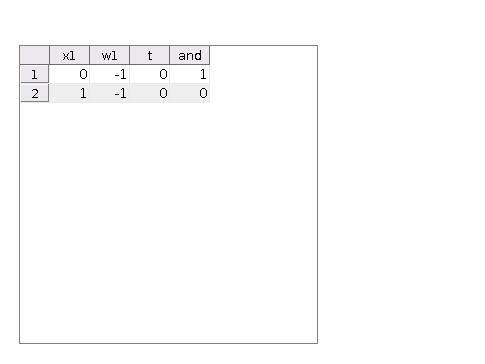

% Part B
% NOT Gate

x1 = [0, 1];
w1 = [-1, -1];
t = 0;

not = {'x1' 'w1' 't' 'and'};
data=[];
for i = 1:length(x1)
    if ( x1(i)*w1(i) ) >= t
        datas = [x1(i), w1(i), t, 1];
    else
        datas = [x1(i), w1(i), t, 0];
    end
    data = [data; datas];
end

f=figure;
t=uitable(f, 'data', data, 'columnname', not, 'ColumnWidth', {40});

% Question 2

% Part A
% OR Gate

x = [0 0 1 1; 0 1 0 1];
y = [0 1 1 1];

% network architecture
or=patternnet(2);

% train the neural network
nn=train(or, x, y);

% testing
z = [1 1 0 1; 1 0 1 1];
output=round(nn(z))

output =      1     1     1     1


% Part B
% AND Gate

x = [0 0 1 1; 0 1 0 1];
y = [0 0 0 1];

% network architecture
and=patternnet(2);

% train the neural network
nn=train(and, x, y);

% testing
z = [1 1 0 1; 1 0 1 1];
output=round(nn(z))

output =      1     0     0     1


% Part C
% NOT Gate

x = [0 1];
y = [1 0];

% network architecture
not=patternnet(1);

% train the neural network
nn=train(not, x, y);

% testing
z = [1 0];
output=round(nn(z))

output =      0     1


% Question 3

% Part A
% XOR Gate

x = [0 0 1 1; 0 1 0 1];
y = [0 1 1 0];

% network architecture
xor=feedforwardnet(5);

% train the neural network
nn=train(xor, x, y);

% testing
z = [0 0 1 1; 0 1 1 0];
output=round(nn(z))

output =      0     1     0     1


% Part B

x = [0 0; 0 1; 1 0; 1 1];
y = [0; 1; 1; 0];

% network architecture
input = 2;
hidden = 5;
output = 1;

% weights and biases
weights_IH=randn(hidden, input);
bias_H=randn(hidden, 1);
weights_HO=randn(output, hidden);
bias_O=randn(output, 1);

learning_rate=0.1

learning_rate = 0.1000


% training
for epoch = 1:10000
    % forward pass
    hidden_input=weights_IH*x'+repmat(bias_H, 1, 4);
    hidden_output=sigmoid(hidden_input);
    final_input=weights_HO*hidden_output+bias_O;
    final_output=sigmoid(final_input);
    % backward pass
    error=y'-final_output;
    delta_output=error.*sigmoid_derivative(final_input);
    delta_hidden=(weights_HO'*delta_output).*(sigmoid_derivative(hidden_input));
    % update weights and biases
    weights_HO=weights_HO+learning_rate*delta_output*hidden_output';
    bias_output=bias_O+learning_rate*sum(delta_output, 2);
    weights_IH=weights_IH+learning_rate*delta_hidden*x;
    bias_hidden=bias_H+learning_rate*sum(delta_hidden, 2);
end

% testing
z=round(sigmoid(weights_HO*sigmoid(weights_IH*x'+repmat(bias_H, 1, 4))+bias_O))

z =      0     1     1     0


function s = sigmoid(x)
    s=1./(1+exp(-x));
end

function ds = sigmoid_derivative(x)
    s=sigmoid(x);
    ds=s.*(1-s);
end